# Depth sensing with Monocular Depth Estimation for indoor robot perception

(실내에서 로봇을 활용하기 위한 딥러닝 기반 단안 거리 추정 기술)

## About

In this example, distance can be presumed by using MDE(Monocular Depth Estimation) instead of using Lidar sensor.

The pretrained vision model is used as a backbone to be finetuned into depth estimation model and [NYU Depth Dataset V2](https://cs.nyu.edu/~silberman/datasets/nyu_depth_v2.html) is used to train the model for indoor environment.

Finally, the network will be verifed with a simulink model connected to [Gazebo](https://gazebosim.org/) using ROS Toolbox and one connected to real-world video.

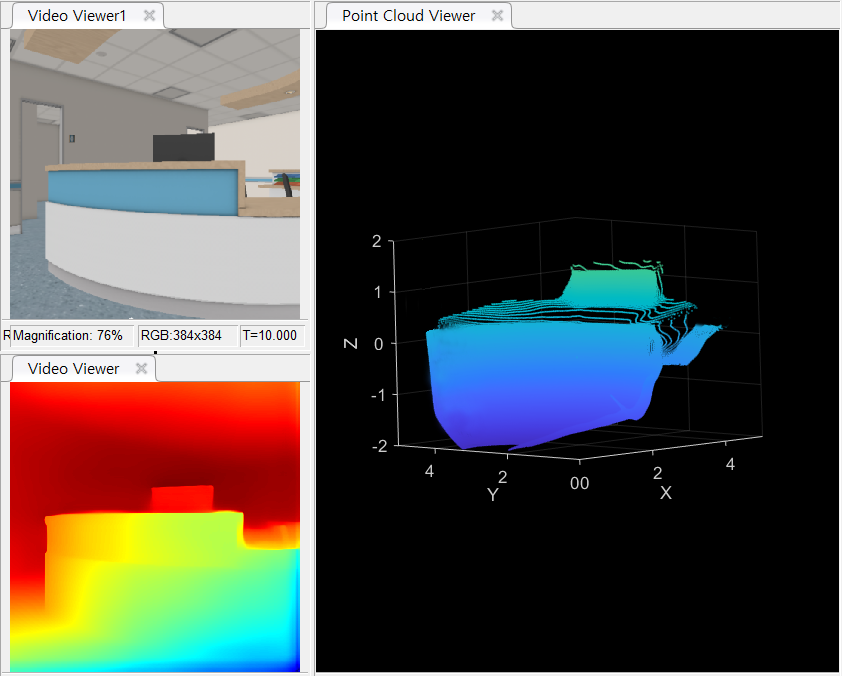

Link to Gazebo simulation

## **Dependencies**

MATLAB

- [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html)

- [Computer Vision Toolbox](https://www.mathworks.com/products/computer-vision.html)

- [Statics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)

- [Lidar Toolbox](https://www.mathworks.com/products/lidar.html)

Simulink

- [Robotics System Toolbox](https://www.mathworks.com/products/robotics.html)

- [Automated Driving Toolbox](https://www.mathworks.com/products/automated-driving.html)

- [ROS Toolbox](https://www.mathworks.com/products/ros.html)

- [Gazebo Simulation Environment Requirements and Limitations](https://kr.mathworks.com/help/robotics/ug/gazebo-simulation-requirements.html)

## 1. Before Training

Define project path

path = fileparts(which('main.mlx'));
addpath(genpath(path));

#### 1.1) Load original dataset

Matlab loads the RGB and Depth dataset from dataset file.  ( NYU dataset should be in dataset folder )

The dataset is [NYU depth V2 dataset](https://cs.nyu.edu/~silberman/datasets/nyu_depth_v2.html) used in the paper [1].

dataset = load('dataset/nyu_depth_v2_labeled.mat');
RGB = permute(dataset.images,[4,1,2,3]); % 1449 480 640 3 uint8
DEP = permute(dataset.depths,[3,1,2]);  % 1449 480 640 single

Resize the dataset into target size for network training.

'target_size' is equal to input size of the designed network

target_size = 384;
dataset_RGB = resize_3C(RGB,target_size);
dataset_DEP = resize_1C(DEP,target_size);
clear RGB DEP 

#### 1.2) Check dataset

Check data with visual

test_num = 20;
test_RGB = squeeze(dataset_RGB(test_num,:,:,:));
test_DEP = squeeze(dataset_DEP(test_num,:,:));

preview_RGB = imshow(test_RGB);
preview_DEP = depthColor(test_DEP); 

## 2. Model

#### 2.1) Design network

Network architecture is designed using [deepNetworkDesigner](https://kr.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html) in [Deep Learning Toolbox](https://kr.mathworks.com/help/deeplearning/index.html).

the network follows the architecture in MiDas paper [2].

ResNet-50 pretrained network is used as a backbone.

deepNetworkDesigner()

#### 2.2) Train network    

train MDE(Monocular Depth Estimation) model with pretrained backbone 

run('train_net.mlx');

#### 2.3) Load trained network

Load the trained dlnetwork

trainResult = load('net_trained_20230724.mat');
% net = trainResult.TrainedNetwork;
net = trainResult.net;
clear trainResult

% load Layergraph to remove output layer
lgraph = net.layerGraph;
% lgraph = lgraph.removeLayers('regression')

trained_net = dlnetwork(lgraph);
clear lgraph

#### 2.4) Test network

test_data = load('test/test_data.mat');
RGB = test_data.test_RGB;
DEP = test_data.test_DEP;
clear test_data

dlX = dlarray(RGB,'SSCB');
dlY = predict(trained_net, dlX);
output = extractdata(dlY);

clear RGB DEP dlX dlY

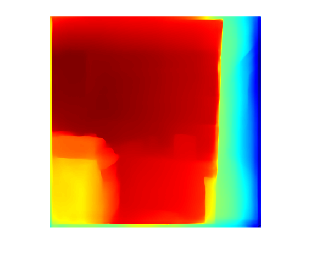

% Convert rel to abs
p = [0 -0.0024 8.2238];
depth_map = 0.4838*(p(2)*output + p(3)) + 3.129;
depthColor(depth_map);


clear output p

#### 2.5) Transform depth map into point cloud in MATLAB

Each pixels in depth out is transformed into point cloud format with camera's physical parameter.

fov = 80; % from Camera Parameters

width = 384; height = 384;
pixels = width*height; % from Resolution
crop = 5;
min_distance = 0;
max_distance = 6;

cnt = 1;    
pnt_pol = zeros([pixels,3]);

for i=1+crop:(height)-crop %세로
    for j=1+crop:(width)-crop %가로

        test_depth = depth_map;

        distance = test_depth(i,j);
        %% 기준각 pi/4
        angle_vert = -((2 * (i - 1) / (height - 1)) - 1);  % 1 -> 1, 480 -> -1  
        angle_hor = -((2 * (j - 1) / (width -        1)) - 1);  % 1 -> 1, 640 -> -1
        theta = pi/4 + deg2rad(fov/2)*angle_hor;
        rho = distance * cos(abs(deg2rad(fov/2)*angle_hor)); 
        z = distance * sin(abs(deg2rad(fov/2)*angle_vert)) *sign(angle_vert);    % 절대값 높이 * 부호
       
        % polar to cartsian coordinate
        [x,y,z] = pol2cart(theta,rho,z);
        if distance < max_distance  && distance > min_distance
        pnt_pol(cnt,:) = [x,y,z];
        end
        cnt = cnt+1;
    end
end 

% ptcloud format transform & plot
ptCloud = pointCloud(pnt_pol)

ptCloud =   pointCloud with properties:

     Location: [147456×3 double]
        Count: 147456
      XLimits: [0 4.7622]
      YLimits: [0 5.1211]
      ZLimits: [-3.2442 3.2921]
        Color: []
       Normal: []
    Intensity: []


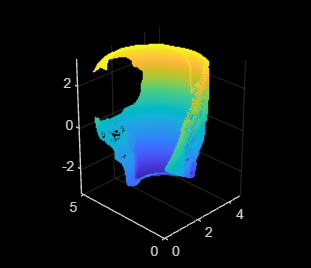

pcshow(ptCloud) 

## 3. Deployment

#### 3.1) Test model on Gazebo environment

Gazebo simulation send camera sensor message to simulink Gazebo block.

Loaded dlnetwork print depth out and function blocks calculate it into pointcloud data.

% deploy model on simulink
open_system('simulink_gazebo.slx');

#### 3.2) Test model for real-world video

Depth model is tested with real world video

% deploy model on simulink
original_resolution = [1525 1016];
open_system('simulink_realworld.slx');

[1] *Silberman et al. (2012). Indoor Segmentation and Support Inference from RGBD Images. – ECCV 2012*

*[2] *Ranftl, René, et al. "Towards robust monocular depth estimation: Mixing datasets for zero-shot cross-dataset transfer." *IEEE transactions on pattern analysis and machine intelligence* 44.3 (2020): 1623-1637